# High Voltage Battery - Test Case

## LoadCurrentStep3 - Vary Load Current

mdl = "BatteryHV_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

BatteryHV_harness_setup

sigBuilder = BatteryHV_InputSignalBuilder;
sigBuilder.Plot_tf = true;

% Initial conditions
ini_Temp_degC = 8;
ini_SOC_pct = 50;
ini_Chg_Ahr = batteryHV.nominalCharge_Ahr * ini_SOC_pct/100

ini_Chg_Ahr = 5.7143

CRateUnit_A = batteryHV.nominalCharge_Ahr

CRateUnit_A = 11.4286

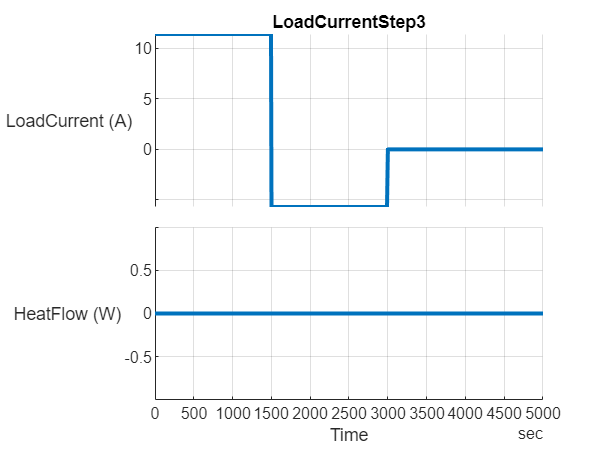

inpData = LoadCurrentStep3(sigBuilder, ...
      InitialSOC_pct = ini_SOC_pct, ...
      InitialCharge_Ahr = ini_Chg_Ahr, ...
      InitialTemperature_degC = ini_Temp_degC, ...
      HeatFlow_Const_W = 0, ...
      LoadCurrent_1_A = 1*CRateUnit_A, ...
      LoadCurrent_2_A = -0.5*CRateUnit_A, ...
      LoadCurrent_3_A = 0, ...
      LoadCurrentChange_1_StartTime = seconds(1500), ...
      LoadCurrentChange_1_EndTime   = seconds(1500 + 1), ...
      LoadCurrentChange_2_StartTime = seconds(1501 + 1499), ...
      LoadCurrentChange_2_EndTime   = seconds(3000 + 1), ...
      StopTime = seconds(5000) );

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));
t_end = inpData.Options.StopTime_s;

batteryHV_InputSignals = inpData.Signals;
batteryHV_InputBus = inpData.Bus;

assert(inpData.Options.InitialCharge_Ahr == ini_Chg_Ahr)
initial.hvBattery_Charge_Ahr = inpData.Options.InitialCharge_Ahr;

ambient.temp_K =  273.15 + inpData.Options.InitialTemperature_degC;
initial.hvBattery_Temperature_K = ambient.temp_K;

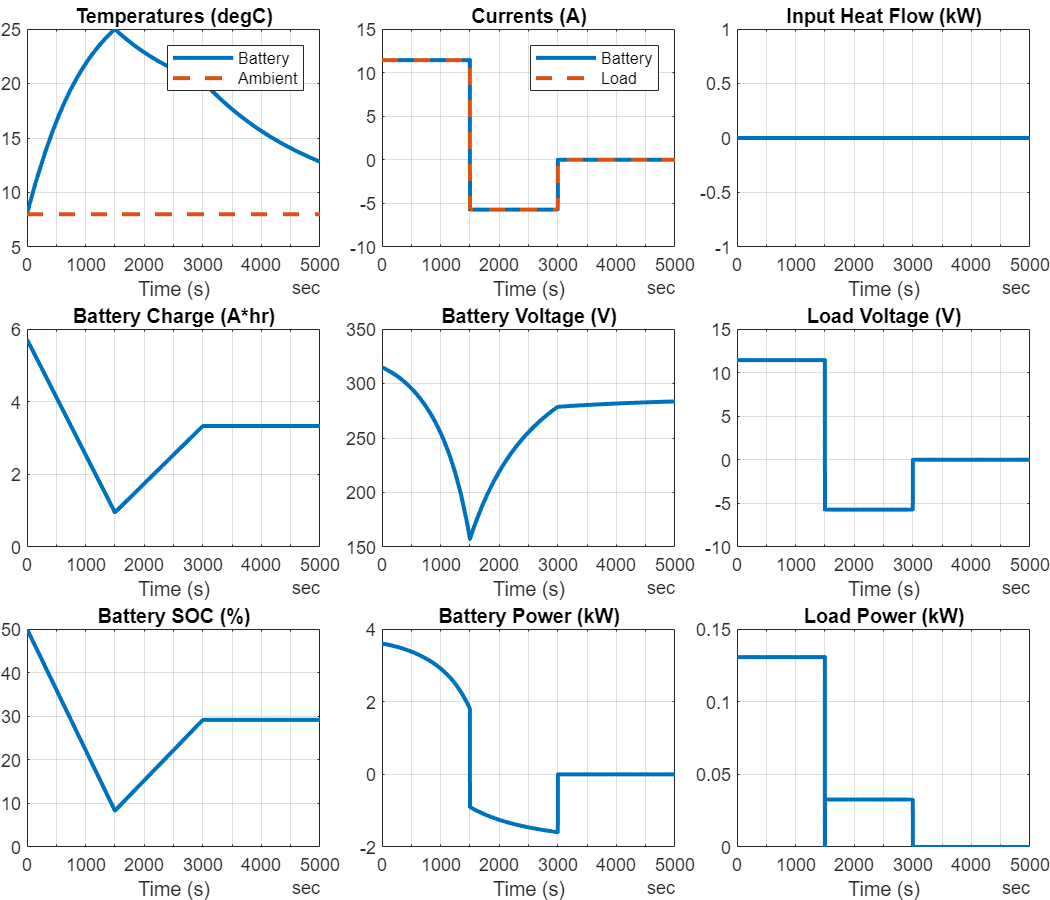

simOut = sim(simIn);

logged_signals = extractTimetable(simOut.logsout);
BatteryHV_plotResults(logged_signals);

*Copyright 2020-2022 The Mathworks, Inc.*